# 1.1

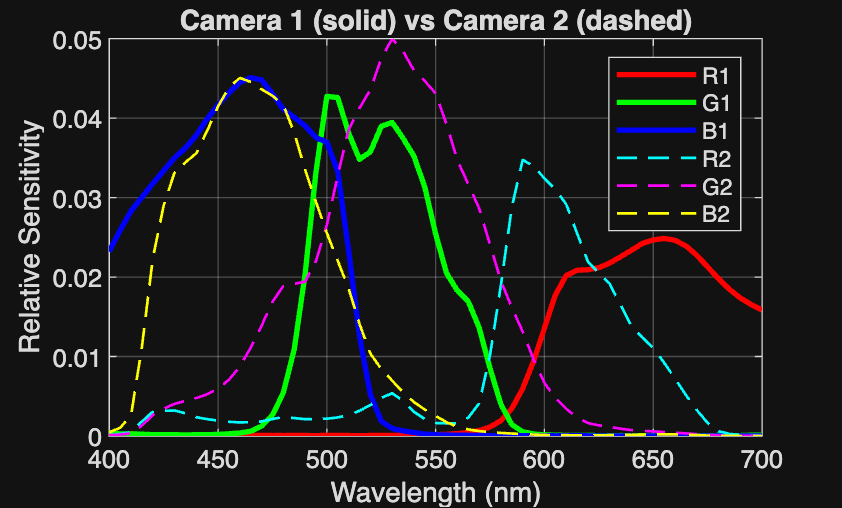

load("Ad.mat")
load("Ad2.mat")
load("illum.mat")

figure;
plot(waverange, Ad(:,1), 'r', 'LineWidth', 2); hold on;
plot(waverange, Ad(:,2), 'g', 'LineWidth', 2);
plot(waverange, Ad(:,3), 'b', 'LineWidth', 2);

plot(waverange, Ad2(:,1), 'c--', 'LineWidth', 1);
plot(waverange, Ad2(:,2), 'm--', 'LineWidth', 1);
plot(waverange, Ad2(:,3), 'y--', 'LineWidth', 1);

grid on;
xlabel('Wavelength (nm)');
ylabel('Relative Sensitivity');
title('Camera 1 (solid) vs Camera 2 (dashed)');
legend('R1', 'G1', 'B1', 'R2', 'G2', 'B2');

# 1.2

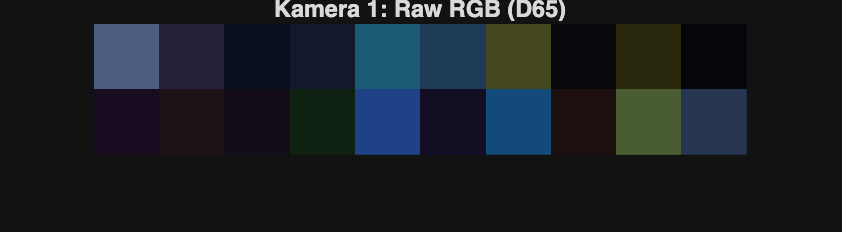

load("chips20.mat")
load("Ad.mat")
load("Ad2.mat")
load("illum.mat")

E = chips20 .* CIED65;

RGB_raw_D65_cam1 = E * Ad;
RGB_raw_D65_cam2 = E * Ad2;

showRGB(RGB_raw_D65_cam1);
title('Kamera 1: Raw RGB (D65)');

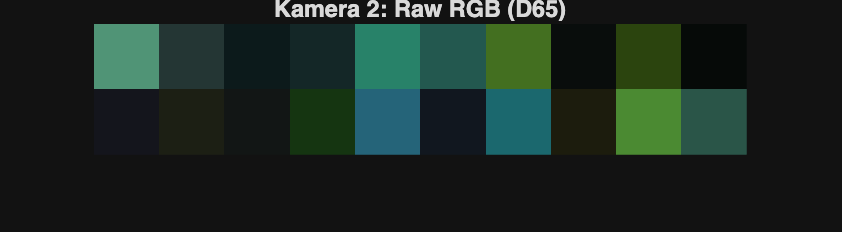


showRGB(RGB_raw_D65_cam2);
title('Kamera 2: Raw RGB (D65)');

# 2.1

e = ones(1,61);
normAd = Ad'*e'

normAd =     0.4635
    0.5646
    0.8585


normAd2 = Ad2'*e'

normAd2 =     0.4726
    0.8747
    0.7420


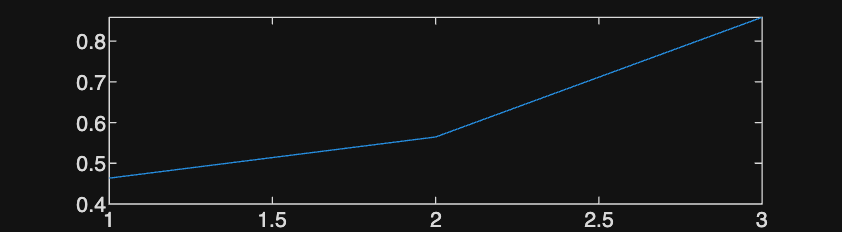



plot(normAd)

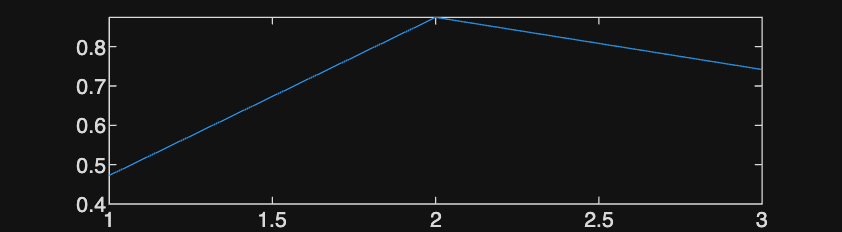

plot(normAd2)

# 2.2

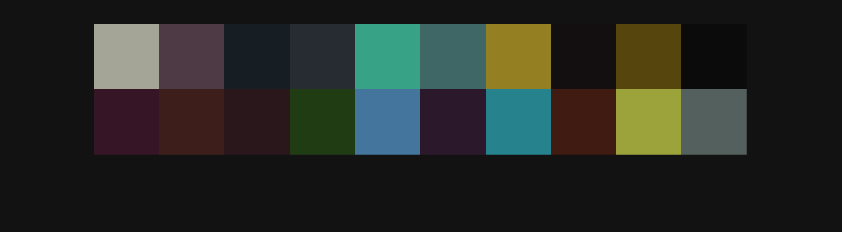

RGB_cal_D65_Ad = (Ad'*(chips20(:,:).*CIED65)')./normAd
RGB_cal_D65_Ad2 = (Ad2'*(chips20(:,:).*CIED65)')./normAd2

showRGB(RGB_cal_D65_Ad')

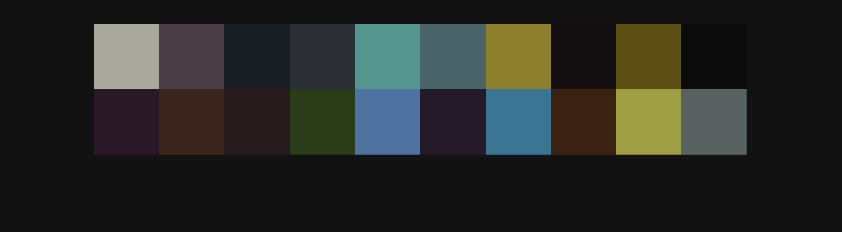

showRGB(RGB_cal_D65_Ad2')

# 2.3

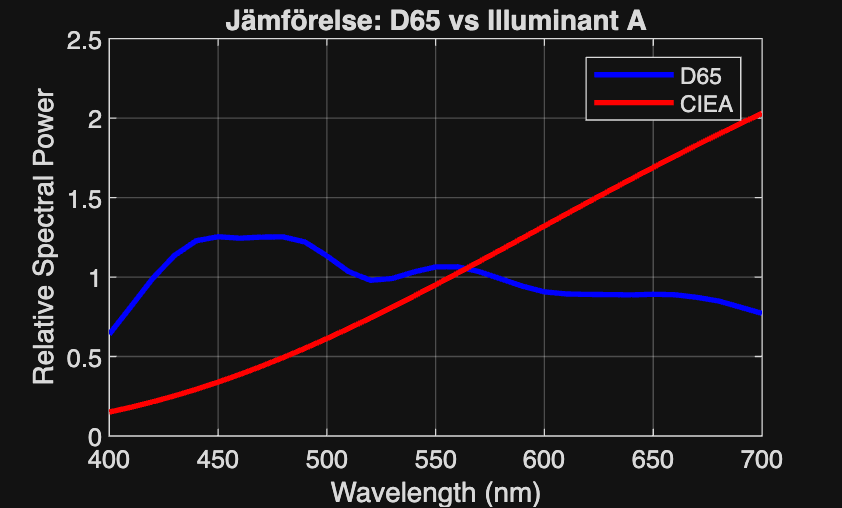

figure;
plot(waverange, CIED65, 'b', 'LineWidth', 2); hold on;
plot(waverange, CIEA, 'r', 'LineWidth', 2);

grid on;
xlabel('Wavelength (nm)');
ylabel('Relative Spectral Power');
title('Jämförelse: D65 vs Illuminant A');
legend('D65', 'CIEA');

# 2.4

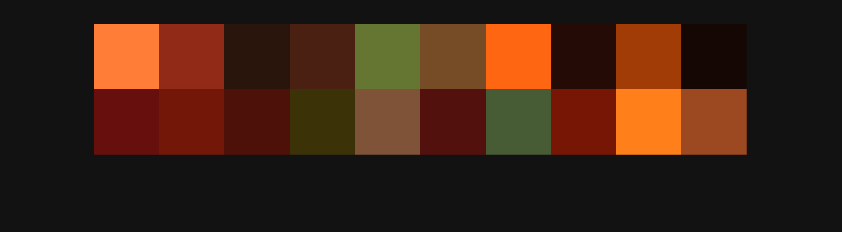

load("Ad.mat");
e = ones(1,61);
normAd = Ad'*e';
RGB_cal_A_Ad = Ad'*(chips20(:,:).*CIEA)'./normAd;

showRGB(RGB_cal_A_Ad')

showRGB(RGB_cal_D65_Ad')

# 2.5

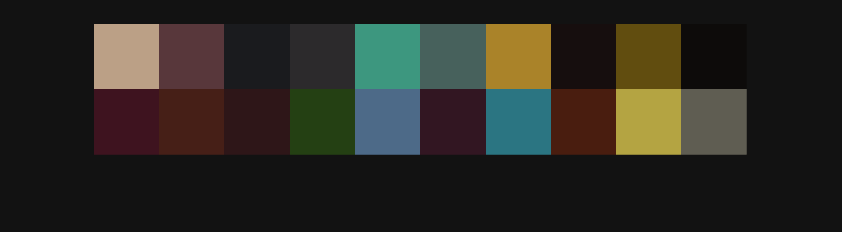

load("Ad.mat");
load('chips20.mat')
load('illum.mat')
R = ones(1,61);

Cal_A = Ad'*(R.*CIEA)';
RGB_RAW_A = Ad'*(chips20(:,:).*CIEA)'./Cal_A;
showRGB(RGB_RAW_A')

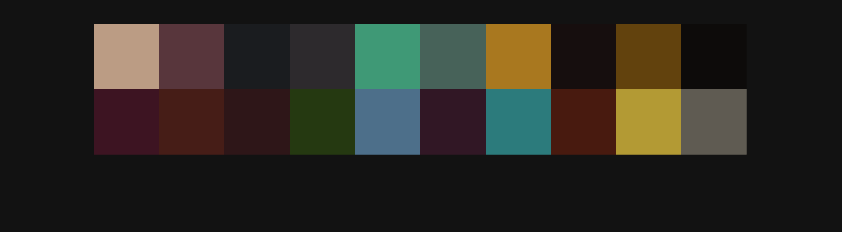


Cal_D65 = Ad'*(R.*CIED65)';
RGB_RAW_D65 = Ad'*(chips20(:,:).*CIED65)'./Cal_D65;
showRGB(RGB_RAW_D65')

# 3.1

load("Ad.mat")
load('chips20.mat')
load('illum.mat')
load("xyz.mat")


k = 100./(CIED65*xyz(:,2))

k = 4.6460

XYZ_D65_ref = xyz'*( CIED65 .* chips20 )' * k

XYZ_D65_ref =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082


# 3.2

load("M_XYZ2RGB.mat")

MXYZ = inv(M_XYZ2RGB) * RGB_cal_D65_Ad;
%Matrix

[L, a, b] =  xyz2lab(MXYZ(1,:)', MXYZ(2,:)', MXYZ(3,:)');

C_LAB = zeros(3,20);
C_LAB(1,:) = L;
C_LAB(2,:) = a;
C_LAB(3,:) = b;

[L, a, b] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;
    
dE = sqrt((C_LAB(1,:)-REF_LAB(1,:)).^2+(C_LAB(2,:)-REF_LAB(2,:)).^2+(C_LAB(3,:)-REF_LAB(3,:)).^2);

dE_Mean = mean(dE)

dE_Mean = 12.6418

dE_Max = max(dE)

dE_Max = 31.6232

# 3.3

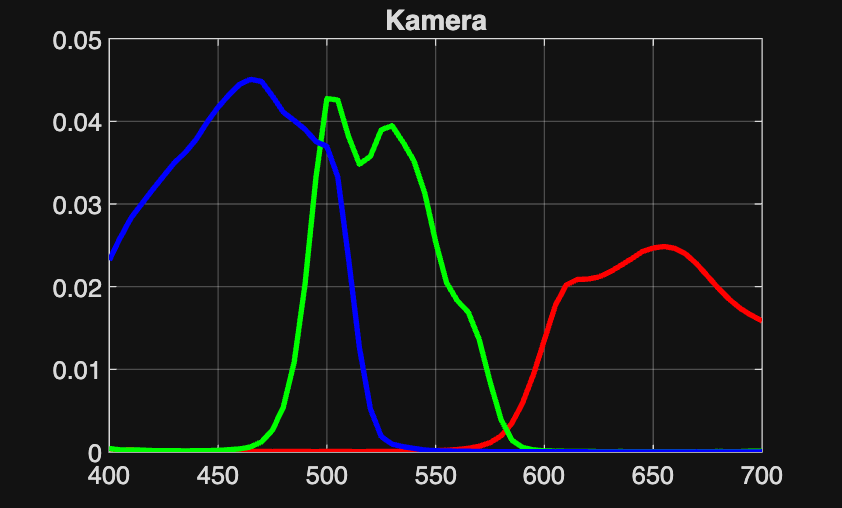

figure;
plot(waverange, Ad(:,1), 'r', 'LineWidth', 2); hold on;
plot(waverange, Ad(:,2), 'g', 'LineWidth', 2);
plot(waverange, Ad(:,3), 'b', 'LineWidth', 2);
grid on;
title('Kamera');

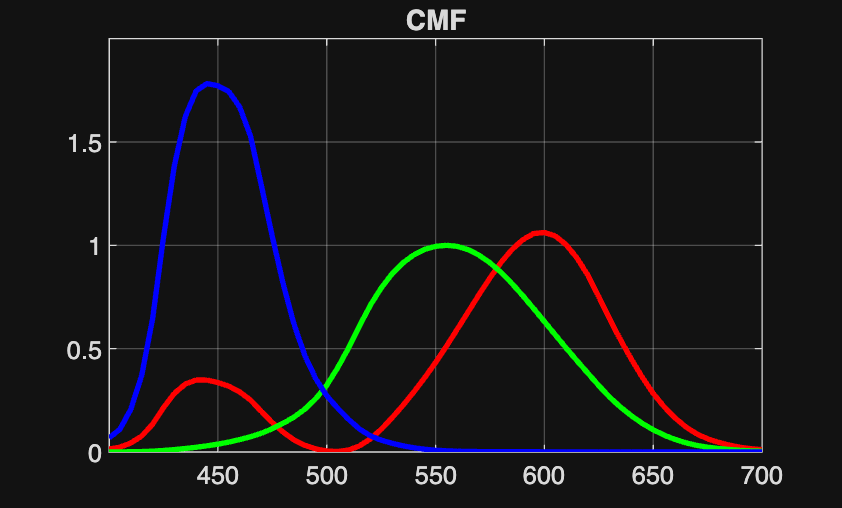


figure;
plot(waverange, xyz(:,1), 'r', 'LineWidth', 2); hold on;
plot(waverange, xyz(:,2), 'g', 'LineWidth', 2);
plot(waverange, xyz(:,3), 'b', 'LineWidth', 2);
title('CMF');
grid on;

# 3.4

A = pinv(RGB_cal_D65_Ad') * XYZ_D65_ref';

estimate = RGB_cal_D65_Ad'*A;
dE2 = ComputeEuclidean_Distance(XYZ_D65_ref, estimate');
dE_Mean2 = mean(dE2)

dE_Mean2 = 2.1977

dE_Max2 = max(dE2)

dE_Max2 = 5.8376

# 3.5

A = Optimize_poly(RGB_cal_D65_Ad, XYZ_D65_ref);
estimate = Polynomial_regression(RGB_cal_D65_Ad, A);
e = ComputeEuclidean_Distance(XYZ_D65_ref, estimate);
mean(e)

ans = 1.0238

max(e)

ans = 3.1053